path = 'D:\MATLAB2022\projects\vpd_robotics\lab5\plotting';
Name = 'testing_p_controller_theta_10_0_0';
fullpath = fullfile(path, Name);
saveas(gcf, fullpath, 'png');

Выбираем числа $a,t_1 ,t_2$ , что $t_1 <t_2$. 

Берём функцию g, что 


$$g\left(t\right)=\left\lbrace \begin{array}{ll}
a & t\in \left\lbrack t_1 ,t_2 \right\rbrack \\
0 & ,\textrm{else}
\end{array}\right.$$


% Задайте значения параметров a, t1 и t2
a = 3;
t1 = -2;
t2 = 4;

Теперь возьмём большой интервал времени $T$ и маленький шаг дискретизации $\textrm{dt}$

T = 20;
dt = 0.01;
% Создайте диапазон значений t
t=-T/2:dt:T/2;

Найдём зашумлённую версию сигнала как


$$u=g+b*\left(\textrm{rand}\left(\textrm{size}\left(t\right)\right)-0\ldotp 5\right)+c*\sin \left(d*t\right);$$


% зададим дополнительные коэффиценты - на рандом пока что
b = 1; 
c = 0; 
d = 0;

Построим график фильтра

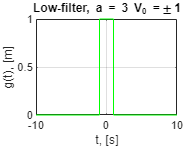

% Зададим диапазон чистки --> [-V0; V0]
V0 = T/20;
V1 = T/10;
plotFilter(1, t, V0,V1, a);


select = 1;

u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
U = fftshift(fft(u)); % Прямое преобразование (быстрое)


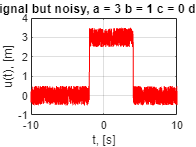

plotSignal(t, t1,t2, a,b,c,d)

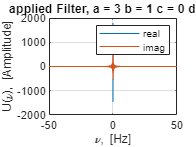

figure( randi([1 3000],1,1) )

u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
U = fftshift(fft(u));

 if (select == 1)
    g_t = g_odd(t, V0);
elseif (select == 2)
    g_t = g_even(t, V0, V1);
else
    g_t = g_inv(t, V0);
end


V = 1/dt; % Ширина диапазона частот
dv = 1/T; % Шаг частоты 
v = -V/2 : dv : V/2; % Набор частот для FFT

plot(v, real(U).*g_t);
hold on
plot(v, imag(U).*g_t);
legend('real','imag')
%     xlim([-12; 12]);
title("applied Filter, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d)
grid on;
xlabel('\nu, [Hz]');
ylabel('U(\nu), [Amplitude]');
hold off;

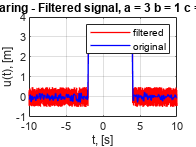

    figure( randi([1 3000],1,1) )
    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    U = fftshift(fft(u));
    
     if (select == 1)
        g_t = g_odd(t, V0);
    elseif (select == 2)
        g_t = g_even(t, V0, V1);
    else
        g_t = g_inv(t, V0);
    end

    pure = U.*g_t;
    u_new = ifft(ifftshift(pure)); % Обратное преобразование
    plot(t, u, 'LineWidth', 1, 'Color', [1 0 0 0.3]);
    hold on;
    plot(t, u_new, 'LineWidth', 1, 'Color', [0 0 1 0.3]);
%     alpha(s,.2)
    title("Comparing - Filtered signal, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d)
    legend('filtered', 'original')
    grid on
%     xlim([t1, t2]);
    xlabel('t, [s]');
    ylabel('u(t), [m]');
    hold off;

### Первое задание

***Вспомогательная функция для помех***

function y = g(t, a, t1, t2)
    y = a * (heaviside(t - t1) - heaviside(t - t2));
end

**Фильтр высоких частот**

function y = g_inv(t, V0)
y = 1 - (heaviside(t + V0) - heaviside(t - V0));
end

**Фильтр специфических частот**

function y = g_even(t, V0, V1)
    y = (heaviside(t - V0) - heaviside(t - V1)) + (heaviside(-t - V0) - heaviside(-t - V1));
end

**Фильтр низких частот**

function y = g_odd(t, V0)
    y = (heaviside(t + V0) - heaviside(t - V0));
end


function plotSignal(t, t1,t2, a,b,c,d)
    figure( randi([1 3000],1,1) )

    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    plot(t, u, 'red');
    title("Signal but noisy, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d)
    grid on;
%     xlim([t1, t2]);
    xlabel('t, [s]');
    ylabel('u(t), [m]');
    hold off;
end


function plotFilter(select, t, V0,V1, a)
    figure( randi([1 3000],1,1) )

    if (select == 1)
        g_t = g_odd(t, V0);
    elseif (select == 2)
        g_t = g_even(t, V0, V1);
    else
        g_t = g_inv(t, V0);
    end
    plot(t, g_t, 'green');

    if (select == 1)
        title("Low-filter, " + "a = "+a+" V_0 =\pm"+V0)
    elseif (select == 2)
        title("Specific-filter, " + "a = "+a+" V_0 = "+V0+" V_1 = "+V1)
    else
        title("High-filter, " + "a = "+a+" V_0 =\pm"+V0)
    end

    grid on
    xlabel('t, [s]');
    ylabel('g(t), [m]');
    hold off;
end